% Import data
data_HW3 = readtable("Top 100 Genes.xlsx","ReadRowNames",true);

% Inspect table
head(data_HW3,5)

ans = 5×101 table
                          A_23_P342744            A_24_P246891                 A_23_P24535                                  A_23_P75362                                           A_32_P76399                                         A_23_P102973                                A_23_P133332                                             A_23_P257335                                            A_24_P192988                A_23_P151106                      A_23_P120970                                             A_24_P810290                                   A_23_P131825                               A_23_P206684                                     A_32_P32061                                        A_23_P79122   

test_patients = readcell("Patient IDs - Test Set.xlsx");
train_patients = readcell("Patient IDs - Training Set.xlsx");

% Using readmatrix correctly loads data as class "double"
%data_HW3_2 = readmatrix("Top 100 Genes & Rand 15 Patients.xlsx");

% Create new X and Y matrices (have to convert class if using readtable)
Xtrain = str2double(data_HW3{train_patients, 1:100});
Xtest = str2double(data_HW3{test_patients, 1:100});

Ytrain = table2array(data_HW3(train_patients, end));
Ytest = table2array(data_HW3(test_patients, end));


## Multi-linear Regression using Hold-out Validation

### Normal Regression

% Find correlation of all 100 genes and then extract data for top 15 genes
r_100 = corr(Xtrain,Ytrain);
[r_15,index_15] = maxk(abs(r_100),15);

% Create new training and test predictor data sets with top 15 genes 
Xtrain_15 = Xtrain(:,index_15);
Xtest_15 = Xtest(:,index_15);

mdl = fitlm(Xtrain_15,Ytrain)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    ______    _________    __________

    (Intercept)     627.65     54.797       11.454    2.7843e-12
    x1               163.8     175.67      0.93244       0.35881
    x2             -31.076     115.96     -0.26799       0.79061
    x3             -1.6132     93.205    -0.017308       0.98631
    x4               -4.73      140.2    -0.033738       0.97332
    x5              252.87     152.73       1.6557       0.10857
    x6              134.88     119.03       1.1332       0.26641
    

Ypred_norm = predict(mdl,Xtest_15);
r_norm = corr(Ytest,Ypred_norm)

r_norm = 0.0816

r2_norm = r_norm^2

r2_norm = 0.0067

RMSE = sqrt(mean((Ypred_norm-Ytest).^2))   

RMSE = 359.6592

avg_error = mean(abs(Ypred_norm-Ytest))

avg_error = 296.3538

### Lasso Regression

[B1, Fit] = lasso(Xtrain_15,Ytrain,'CV',5);
B1_coeff = B1(:,Fit.Index1SE)

B1_coeff =   143.2955
         0
   15.2578
         0
   28.6057
    3.0056
         0
   34.1621
   38.1426
   30.7815


B1_intercept = Fit.Intercept(Fit.Index1SE)

B1_intercept = 599.6518

Ypred_lasso = Xtest_15 * B1_coeff + B1_intercept;

r_lasso = corr(Ypred_lasso,Ytest)

r_lasso = 0.1174

r2_lasso =  r_lasso^2

r2_lasso = 0.0138

RMSE_lasso = sqrt(mean((Ypred_lasso-Ytest).^2))   

RMSE_lasso = 314.1729

avg_error_lasso = mean(abs(Ypred_lasso-Ytest))

avg_error_lasso = 257.2454

### Stepwise Regression

[B2,~,~,~,stats] = stepwisefit(Xtrain_15,Ytrain);

Initial columns included: none
Step 1, added column 1, p=3.57549e-06
Step 2, added column 10, p=0.000962066
Step 3, added column 15, p=0.0485883
Final columns included:  1 10 15 
    'Coeff'       'Std.Err.'    'Status'    'P'         
    [393.7172]    [ 90.9898]    'In'        [9.4619e-05]
    [ -0.3560]    [ 99.5721]    'Out'       [    0.9972]
    [ 64.4157]    [ 69.1039]    'Out'       [    0.3568]
    [ 52.2210]    [ 64.1681]    'Out'       [    0.4206]
    [ 43.3180]    [ 90.0316]    'Out'       [    0.6330]
    [ 42.2050]    [ 67.8657]    'Out'       [    0.5375]
    [ 29.5171]    [ 95.3956]    'Out'       [    0.7586]
    [ 74.9424]    [ 55.4607]    'Out'       [    0.1842]
    [100.5944]    [ 53.7852]    'Out'       [    0.0688]
    [ 65.2065]    [ 31.8982]    'In'        [    0.0474]
    [131.6148]    [ 87.8463]    'Out'       [    0.1419]
    [  5.7396]    [ 88.2548]    'Out'       [    0.9485]
    [ 88.5513]    [ 70.0971]    'Out'       [    0.2138]
    [-38.5347]    [ 82.

Ypred_step = Xtest_15(:,[1,10,15])*B2([1,10,15]) + stats.intercept;
r_stepwise = corr(Ypred_step,Ytest)

r_stepwise = 0.1894

r2_stepwise =  r_stepwise^2

r2_stepwise = 0.0359

RMSE_stepwise = sqrt(mean((Ypred_step-Ytest).^2))   

RMSE_stepwise = 347.2721

avg_error_stepwise = mean(abs(Ypred_step-Ytest))

avg_error_stepwise = 281.9262

## Compare Results of 3 Methods

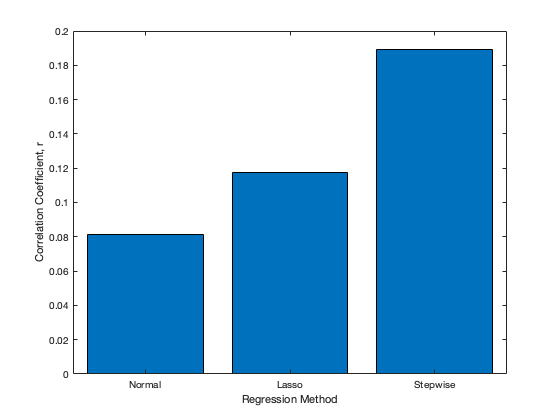

% Create labels for bar graphs
x = categorical({'Normal','Lasso','Stepwise'});
x = reordercats(x,{'Normal','Lasso','Stepwise'});

% Correlation bar graph
bar(x,[r_norm,r_lasso,r_stepwise])
xlabel("Regression Method")
ylabel("Correlation Coefficient, r")

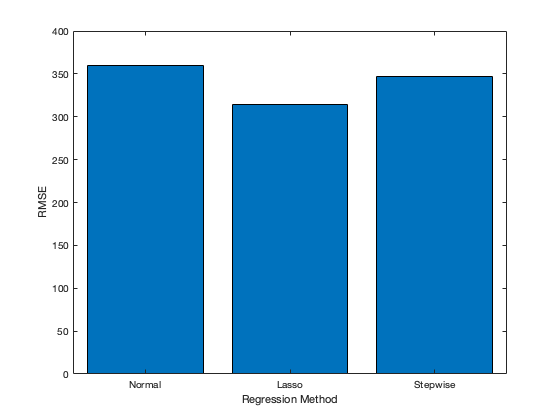

% RMSE bar graph
bar(x,[RMSE,RMSE_lasso,RMSE_stepwise])
xlabel("Regression Method")
ylabel("RMSE")

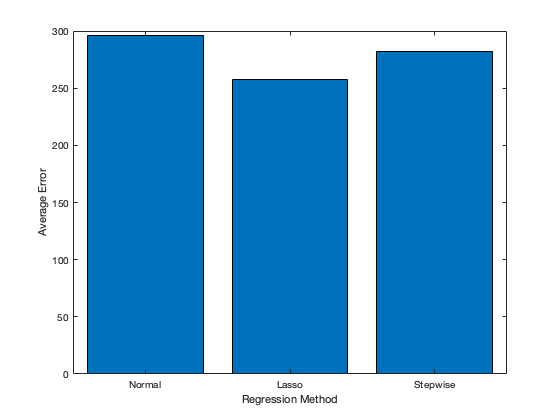

% Avg Error bar graph
bar(x,[avg_error,avg_error_lasso,avg_error_stepwise])
xlabel("Regression Method")
ylabel("Average Error")

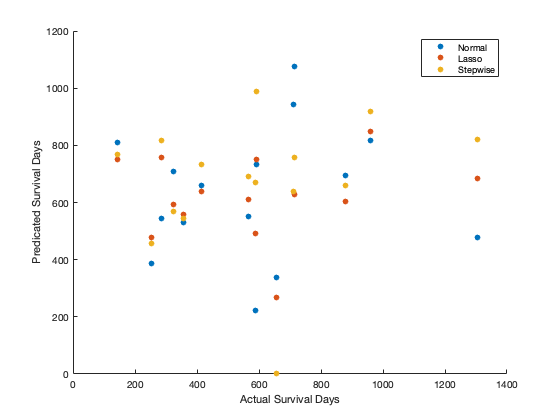

scatter(Ytest,Ypred_norm,"filled")
xlabel("Actual Survival Days")
ylabel("Predicated Survival Days")
hold on
scatter(Ytest,Ypred_lasso,"filled")
hold on
scatter(Ytest,Ypred_step,"filled")
hold off
legend("Normal","Lasso","Stepwise")

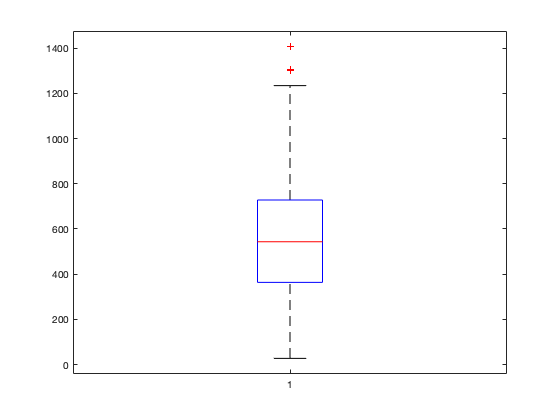

boxplot(data_HW3.SurvivalDays)